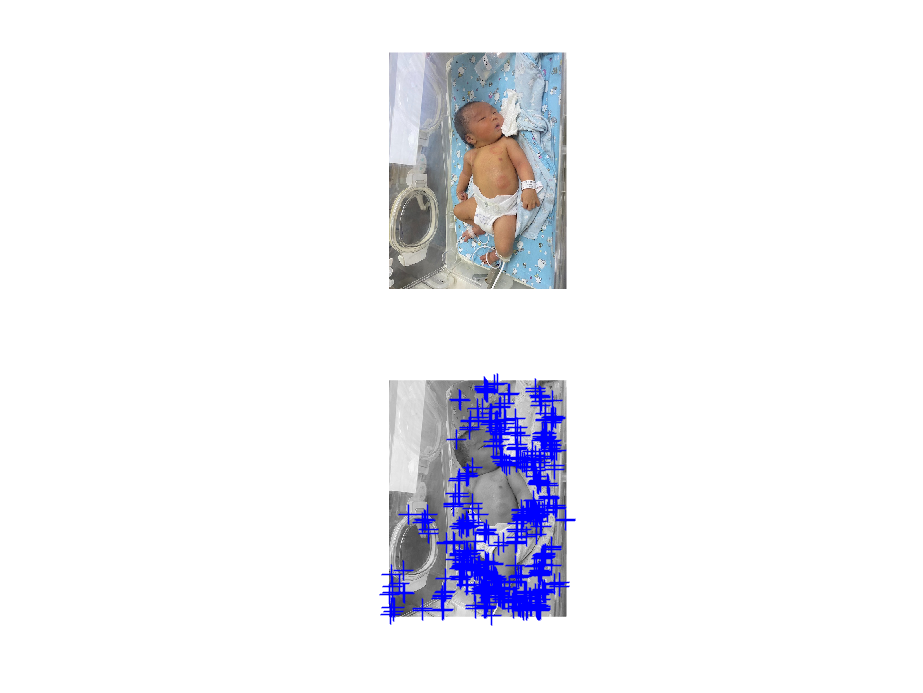

clc;clf;clear;

% convert to grayscale
rgb_baby = imread('baby.jpg');
rgb_word = imread('words.jpg');

gray0_baby = rgb2gray(rgb_baby);
gray0_word = rgb2gray(rgb_word);

gray_baby = double(gray0_baby);
grayb_word = double(gray0_word);

gray_word = imresize(grayb_word, 0.25);
% Gradient Calculation
[rows, cols] = size(gray_baby);
[rowsw, colsw] = size(gray_word);
%dx
dx_sobel = [-1 -2 -0 2 1; -2 -3 0 3 2; -3 -5 0 5 3; -2 -3 0 3 2; -1 -2 0 2 1];
%baby
gray_pd_baby = padarray(gray_baby, [2, 2], 'symmetric');
for i = 1:1:rows-4
    for j = 1:1:cols-4
        temp = gray_pd_baby(i:i+4, j:j+4) .* double((dx_sobel));
         filtered_dx_baby(i,j) = sum(temp(:));
    end
end
%words
gray_pd_word = padarray(gray_word, [2, 2], 'symmetric');
for k = 1:1:rowsw-4
    for q = 1:1:colsw-4
        temp = gray_pd_word(k:k+4, q:q+4) .* double((dx_sobel));
         filtered_dx_word(k,q) = sum(temp(:));
    end
end

%dy
dy_sobel = [1 2 3 2 1; 2 3 5 3 2; 0 0 0 0 0; -2 -3 -5 -3 -2; -1 -2 -3 -2 -1];
for m = 1:1:rows-4
    for n = 1:1:cols-4
        TEMP = gray_pd_baby(m:m+4, n:n+4) .* double((dy_sobel));
         filtered_dy_baby(m,n) = sum(TEMP(:));
    end
end
%words
for a = 1:1:rowsw-4
    for b = 1:1:colsw-4
        TEMP = gray_pd_word(a:a+4, b:b+4) .* double((dy_sobel));
         filtered_dy_word(a,b) = sum(TEMP(:));
    end
end

%gradient product calculation
%baby
dx2_baby = filtered_dx_baby .^ 2;
dy2_baby = filtered_dy_baby .^ 2;
dxy_baby = filtered_dx_baby .* filtered_dy_baby;
%word
dx2_word = filtered_dx_word .^ 2;
dy2_word = filtered_dy_word .^ 2;
dxy_word = filtered_dx_word .* filtered_dy_word;

%gaussian filtering
core_size = 5;
sigma = 1.5;
fil_baby_x2 = guassion_filter(core_size, sigma, dx2_baby);
fil_baby_y2 = guassion_filter(core_size, sigma, dy2_baby);
fil_baby_xy = guassion_filter(core_size, sigma, dxy_baby);
[rb, cb] = size(fil_baby_xy);

fil_word_x2 = guassion_filter(core_size, sigma, dx2_word);
fil_word_y2 = guassion_filter(core_size, sigma, dy2_word);
fil_word_xy = guassion_filter(core_size, sigma, dxy_word);
[rw, cw] = size(fil_word_xy);
%Harris response 

%baby
for i = 1:1:rb
    for j = 1:1:cb
        A = [fil_baby_x2(i,j) fil_baby_xy(i,j); fil_baby_xy(i,j) fil_baby_y2(i,j)];
        R_b(i,j) = det(A) - 0.04*(trace(A)^2);
    end
end

max_Rb = max(R_b(:));
THb = 0.01*max_Rb;
[xb,yb] = size(R_b);
for i = 1:1:xb
    for j = 1:1:yb
        if R_b(i,j) < THb
            R_b(i,j) = 0;
        end
    end
end

for i = 1:xb-2
    for j = 1:yb-2
        temp_img = R_b(i:i+2, j:j+2);
        MAX = max(temp_img(:));
        for temp_i = 1:3
            for temp_j = 1:3
                if temp_img(temp_i, temp_j) < MAX
                    temp_img(temp_i, temp_j) = 0;
                end
            end
        end
        R_b(i:i+2, j:j+2) = temp_img;
    end
end

[point_y, point_x] = find(R_b > 0);
figure
subplot(2,1,1),imshow(rgb_baby)
subplot(2,1,2),imshow(gray_baby,[])
hold on
plot(point_x, point_y, 'b+', 'Markersize', 6)
hold off

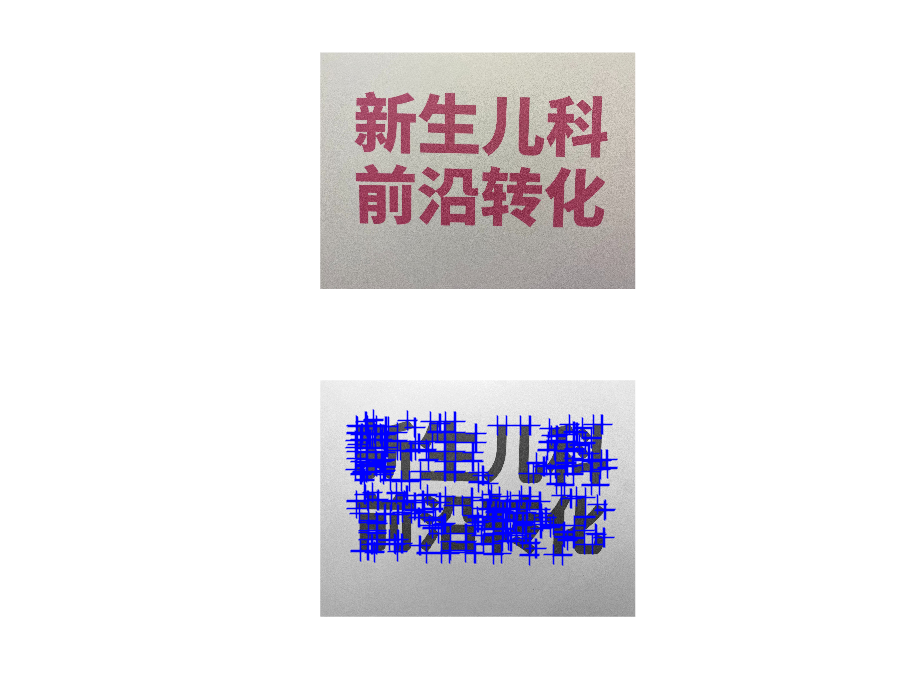


%word
for i = 1:1:rw
    for j = 1:1:cw
        A = [fil_word_x2(i,j) fil_word_xy(i,j); fil_word_xy(i,j) fil_word_y2(i,j)];
        R_w(i,j) = det(A) - 0.04*(trace(A)^2);
    end
end

max_Rw = max(R_w(:));
THw = 0.01*max_Rw;
[xw,yw] = size(R_w);
for i = 1:1:xw
    for j = 1:1:yw
        if R_w(i,j) < THw
            R_w(i,j) = 0;
        end
    end
end

for i = 1:xw-2
    for j = 1:yw-2
        temp_img = R_w(i:i+2, j:j+2);
        MAX = max(temp_img(:));
        for temp_i = 1:3
            for temp_j = 1:3
                if temp_img(temp_i, temp_j) < MAX
                    temp_img(temp_i, temp_j) = 0;
                end
            end
        end
        R_w(i:i+2, j:j+2) = temp_img;
    end
end

[point_yw, point_xw] = find(R_w > 0);
figure
subplot(2,1,1),imshow(rgb_word)
subplot(2,1,2),imshow(gray_word,[])
hold on
plot(point_xw, point_yw, 'b+', 'Markersize', 6)
hold off

function ImFiltered = guassion_filter(core_size, sigma, img)
    orig = (core_size + 1)/2;
    for x = 1:1:core_size
    for y = 1:1:core_size
        temp = abs(x-orig)^2 + abs(y-orig)^2;
        kernel(x,y) = exp(-(temp/(sigma^2))/2) / (2*pi*sigma^2);
    end
    end
pad_img = padarray(img, [2, 2], 'symmetric');
[rows, cols] = size(pad_img);
for i = 1:1:rows-4
    for j = 1:1:cols-4
        TEMP = pad_img(i:i+core_size-1, j:j+core_size-1);
        conv_temp = TEMP .* kernel;
        ImFiltered(i,j) = sum(conv_temp(:));
    end
end

end
